## Set up the Import Options and import the data

opts = spreadsheetImportOptions("NumVariables", 65);

% Specify sheet and range
opts.Sheet = "Supplementary material_final";
opts.DataRange = "A3:BM132";

% Specify column names and types
opts.VariableNames = ["VarName1", "Ageyears", "Gender", "Var4", "AgeOfDiseaseOnsetyears", "DurationOfDiseaseFromFirstSymptomsyears", "Var7", "Var8", "Var9", "Var10", "Var11", "Var12", "Var13", "UPDRSIIITotal", "Var15", "Var16", "Var17", "Var18", "Var19", "Var20", "Var21", "Var22", "Var23", "Var24", "Var25", "Var26", "Var27", "Var28", "Var29", "Var30", "Var31", "Var32", "Var33", "Var34", "Var35", "Var36", "Var37", "Var38", "Var39", "Var40", "Var41", "EST_R", "RST_R", "AST_R", "DPI_R", "DVI_R", "GVI_R", "DUS_R", "DUF_R", "RLR_R", "PIR_R", "RSR_R", "LRE_R", "EST_M", "RST_M", "AST_M", "DPI_M", "DVI_M", "GVI_M", "DUS_M", "DUF_M", "RLR_M", "PIR_M", "RSR_M", "LRE_M"];
opts.SelectedVariableNames = ["VarName1", "Ageyears", "Gender", "AgeOfDiseaseOnsetyears", "DurationOfDiseaseFromFirstSymptomsyears", "UPDRSIIITotal", "EST_R", "RST_R", "AST_R", "DPI_R", "DVI_R", "GVI_R", "DUS_R", "DUF_R", "RLR_R", "PIR_R", "RSR_R", "LRE_R", "EST_M", "RST_M", "AST_M", "DPI_M", "DVI_M", "GVI_M", "DUS_M", "DUF_M", "RLR_M", "PIR_M", "RSR_M", "LRE_M"];
opts.VariableTypes = ["string", "double", "categorical", "char", "double", "double", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify variable properties
opts = setvaropts(opts, ["VarName1", "Var4", "Var7", "Var8", "Var9", "Var10", "Var11", "Var12", "Var13", "Var15", "Var16", "Var17", "Var18", "Var19", "Var20", "Var21", "Var22", "Var23", "Var24", "Var25", "Var26", "Var27", "Var28", "Var29", "Var30", "Var31", "Var32", "Var33", "Var34", "Var35", "Var36", "Var37", "Var38", "Var39", "Var40", "Var41"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["VarName1", "Gender", "Var4", "Var7", "Var8", "Var9", "Var10", "Var11", "Var12", "Var13", "Var15", "Var16", "Var17", "Var18", "Var19", "Var20", "Var21", "Var22", "Var23", "Var24", "Var25", "Var26", "Var27", "Var28", "Var29", "Var30", "Var31", "Var32", "Var33", "Var34", "Var35", "Var36", "Var37", "Var38", "Var39", "Var40", "Var41"], "EmptyFieldRule", "auto");

% Import the data
data = readtable("data.xls", opts, "UseExcel", false);
clear opts


groups(1:30,1) = categorical("PD");
groups(31:80,1) = categorical("RBD");
groups(81:130,1) = categorical("HC");
gender = data.Gender;

data(:,7:end) = filloutliers(data(:,7:end),nan);

## Normality testing

normality = ["Group" data.Properties.VariableNames(7:end)];
normality = cellstr(normality)
normality{2,1} = "PD";
normality{3,1} = "RBD";
normality{4,1} = "HC";
normality{5,1} = "Combined";

for i = 1:24
    x = data(:,i+6);
    x1 = x{1:30,:};
    x2 = x{31:80,:};
    x3 = x{81:130,:};
    [~,normality{2,i+1},~] = swtest(rmoutliers(x1),0.05);
    [~,normality{3,i+1},~] = swtest(rmoutliers(x2),0.05);
    [~,normality{4,i+1},~] = swtest(rmoutliers(x3),0.05);
    [~,normality{5,i+1},~] = swtest(rmoutliers([x1 ;x2; x3]),0.05);


end
normality

Zahodit: EST, DUS

## Homogenity testing

homogenity = [data.Properties.VariableNames(7:end)];

for i = 1:24
    x = data{:,i+6};
    
    homogenity{2,i} = vartestn(x,groups,"Display","off");

end
homogenity

Zahodit: EST, DPI, DVI, RSR, LRE

## ANOVA

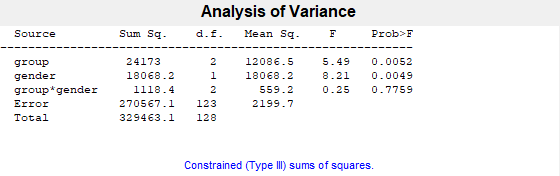

data_adj(:,1) = data(:,20); data_adj.Properties.VariableNames{1,1} = 'RST_M';
data_adj(:,2) = data(:,21); data_adj.Properties.VariableNames{1,2} = 'AST_M';
data_adj(:,3) = data(:,24); data_adj.Properties.VariableNames{1,3} = 'GVI_M';
data_adj(:,4) = data(:,26); data_adj.Properties.VariableNames{1,4} = 'DUF_M';
data_adj(:,5) = data(:,27); data_adj.Properties.VariableNames{1,5} = 'RLR_M';
data_adj(:,6) = data(:,28); data_adj.Properties.VariableNames{1,6} = 'PIR_M';

[~,~,stats] = anovan(data_adj.RST_M,{groups, gender},'varnames',{'group','gender'},'model','interaction');

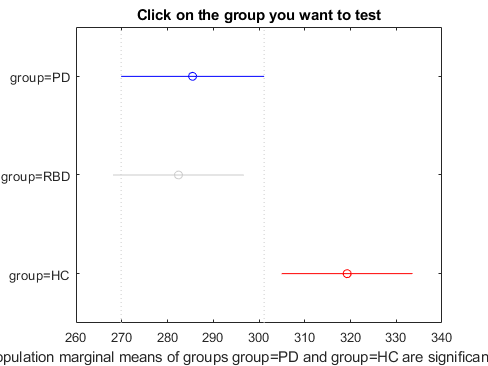

[c,m,h,gnames] = multcompare(stats);

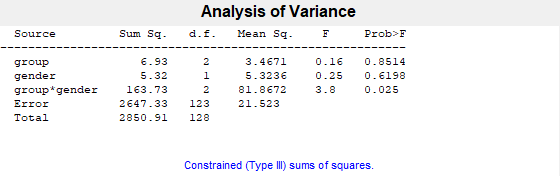



anovan(data_adj.AST_M,{groups, gender},'varnames',{'group','gender'},'model','interaction');

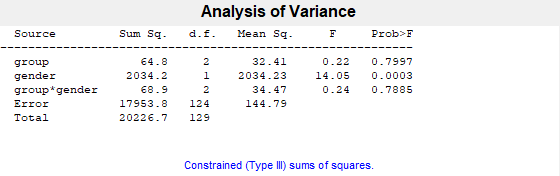


anovan(data_adj.GVI_M,{groups, gender},'varnames',{'group','gender'},'model','interaction');

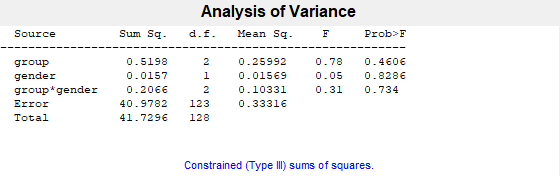


anovan(data_adj.DUF_M,{groups, gender},'varnames',{'group','gender'},'model','interaction');

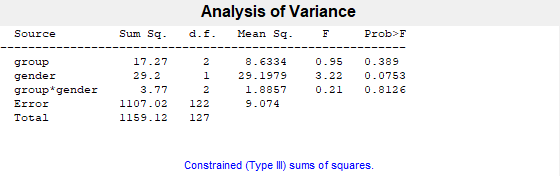


anovan(data_adj.RLR_M,{groups, gender},'varnames',{'group','gender'},'model','interaction');

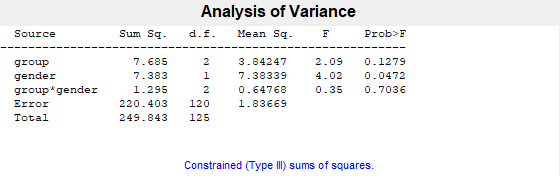


anovan(data_adj.PIR_M,{groups, gender},'varnames',{'group','gender'},'model','interaction');